# Import Pre-Trained Network from TensorFlow

## Introduction

Tiny YOLOv2  is a real-time neural network for object detection that detects 20 different classes. It is made up of 9 convolutional layers and 6 max-pooling layers and is a smaller version of the more complex [YOLOv2](https://pjreddie.com/darknet/yolov2/) network.

## Step 1: Download Tiny YOLOv2 ONNX model

For this example download the TensorFlow [Tiny YOLOv2 ONNX](https://github.com/onnx/models/tree/master/vision/object_detection_segmentation/tiny_yolov2) model from the prebuilt [ONNX Models](https://github.com/onnx/models). Save the downloaded model file as `model.onnx` in the `Utilities` Folder.

## Step 2: Import network using ONNX

Load the ONNX model file

modelfile = fullfile('Utilities','model.onnx');

`importONNXNetwork - `Import a pretrained network from ONNX™ (Open Neural Network Exchange). 

    - `OutputLayerType` - Type of the output layer that the function appends to the end of the imported network, specified as `'classification'`, `'regression'`, or `'pixelclassification'`

net = importONNXNetwork(modelfile,'OutputLayerType','regression')

net =   DAGNetwork with properties:

         Layers: [34×1 nnet.cnn.layer.Layer]
    Connections: [33×2 table]
     InputNames: {'Input_image'}
    OutputNames: {'RegressionLayer_convolution8'}


View the network configuration

analyzeNetwork(net)

## Step 3: Edit the Network using Deep Network Design App

Open the `deepNetworkDesigner` app

useDesignApp = false;
if useDesignApp
    deepNetworkDesigner;
else
    load(fullfile('Utilities','importedTinyYoloLayers.mat'));
end 

In the app:

- In the **File** section, click **Import** and choose the network net that we just imported from ONNX above.

- Edit the network by deleting the final regression layer  to prepare for transfer learning

- Export the network to the MATLAB workspace - in the **Export** section, click **Export**.

- Deep Network Designer can generate MATLAB code for the layer definitions. In the **Export** section, click **Generate MATLAB Code** to generate a live script with the actionable code.

% the exported network is saved as layers_1 in workspace
lgraph = layerGraph(layers_1);


% Compute number of Classes based on Input data.
numClasses = size(trainingData,2)-1;

## Define Anchor boxes

*Anchor boxes* are a set of predefined bounding boxes of a certain height and width. These boxes are defined to capture the scale and aspect ratio of specific object classes you want to detect and are typically chosen based on object sizes in your training datasets. You can define several anchor boxes, each for a different object size. The use of anchor boxes enables a network to detect multiple objects, objects of different scales, and overlapping objects. Read about the [basics of anchor boxes ](https://www.mathworks.com/help/vision/ug/anchor-box-basics.html)here. 

The anchor boxes are selected based on the scale and size of objects in the training data. You can [Estimate Anchor Boxes Using Clustering](https://www.mathworks.com/help/vision/ug/estimate-anchor-boxes-using-clustering-for-deep-learning.html) to determine a good set of anchor boxes based on the training data. Using this procedure, the anchor boxes for the dataset are:

open(fullfile("codeFiles","AnchorBoxes.m"));

Anchors = [43 59
    18 22
    23 29
    84 109];

## Assemble YOLOv2 network

The [yolov2Layers](https://www.mathworks.com/help/vision/ref/yolov2layers.html?s_tid=doc_ta) function creates a YOLO v2 network, which represents the network architecture for YOLO v2 object detector.

`'convolution8'` is the feature extraction layer , The features extracted from this layer are given as input to the YOLO v2 object detection subnetwork. You can specify any network layer except the fully connected layer as the feature layer.

% adding the yolov2 layers with convolution8 as the feature layer
lgraph = yolov2Layers([128 128 3],numClasses,Anchors,net,'activation4');


Visualize the `lgraph` using the `network analyzer app.`

% Visualize the lgraph using the network analyzer.
analyzeNetwork(lgraph);

## Step 4: Perform Transfer Learning training

doTraining = false;
% setting this flag to true will perform transfer learning on the Tiny YOLOv2 detector
% false will load a pre-trained network

if doTraining
    rng(0);

Based on the size of the data set we train the network with the solver - stochastic gradient descent for 80 epochs with initial learning rate of 0.001 and mini-batch size of 16. We performed lower learning rate to give more time for training considering the size of data and adjusting the epoch and mini-batch size. The other approcah could be more epochs like 160 with a higher learning rate of 0.01.  Detailed Documentation to learn about all the options: [trainingOptions](https://www.mathworks.com/help/deeplearning/ref/trainingoptions.html?s_tid=doc_ta).

`ExecutionEnvironment` defines the Hardware resource for training network.

`DispatchInBackground` is used only when parallel training or multi-gpu environment. 

       options = trainingOptions('sgdm', ...
        "LearnRateSchedule","piecewise",...
        'LearnRateDropFactor',0.5,...
        "LearnRateDropPeriod",5,...
        'Verbose',true,'MiniBatchSize',10,'MaxEpochs',100,...
        'Shuffle','every-epoch','VerboseFrequency',50, ...
        'DispatchInBackground',false,...
        'ExecutionEnvironment','auto');

Call the YOLOv2 training function - [trainYOLOv2ObjectDetector](https://www.mathworks.com/help/vision/ref/trainyolov2objectdetector.html?s_tid=doc_ta)

    [detectorTinyYolo2, info] = trainYOLOv2ObjectDetector(table1,lgraph,options);
else
    load(fullfile('Utilities','detectorTinyYolo2.mat')); %pre-trained detector loaded from a MAT-file
end

## Step 5: Evaluation 

Create a table to hold the reults

results = table('Size',[height(TestData) 3],...
    'VariableTypes',{'cell','cell','cell'},...
    'VariableNames',{'Boxes','Scores', 'Labels'}); 

Initialize a Deployable Videl Player to view the image stream

depVideoPlayer = vision.DeployableVideoPlayer;

Loop through all the images in the  Validation set

for i = 1:height(TestData)

    % Read the image
    I = imread(TestData.imageFilename{i});
    
    % Run the detector.
    [bboxes,scores,labels] = detect(detectorTinyYolo2,I);
    
    %         
    if ~isempty(bboxes)
        I = insertObjectAnnotation(I,'Rectangle',bboxes,cellstr(labels));
        depVideoPlayer(I);
        pause(0.1); 
    else 
        depVideoPlayer(I);
    end
    
    
    % Collect the results in the results table
    results.Boxes{i} = floor(bboxes);
    results.Scores{i} = scores;
    results.Labels{i} = labels;

end

threshold =0.3;
expectedResults = TestData;

To evaluate the precision metrics we use [evaluateDetectionPrecision](https://www.mathworks.com/help/vision/ref/evaluatedetectionprecision.html) function. This function here returns the data points for plotting the precison-recall curve using the given input arguments and the threshold value. Extract expected bounding box locations from test data.

[ap, recall, precision] = evaluateDetectionPrecision(results, expectedResults(:,2:end),threshold);

To evaluate miss rate metric for object detection we use the function [evaluateDetectionMissRate](https://www.mathworks.com/help/vision/ref/evaluatedetectionmissrate.html?s_tid=doc_ta)`.`This function returns the log average -miss rate of the results compared to the groundTruthData and data points fpr plotting the log miss rate to false positives per image.  

[am,fppi,missRate] = evaluateDetectionMissRate(results, expectedResults(:,2:end),threshold);

Plot the evaluation metrics for each class

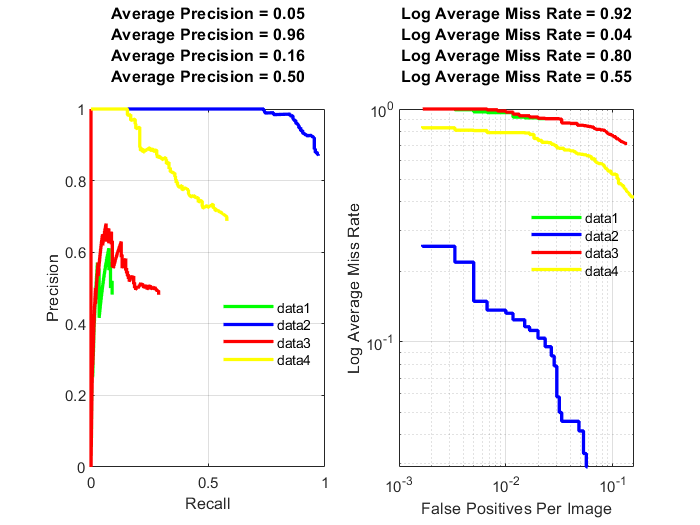

subplot(1,2,1);
plot(recall{1,1},precision{1,1},'g-','LineWidth',2);

hold on;
plot(recall{2,1},precision{2,1},'b-','LineWidth',2);
hold on;
plot(recall{3,1},precision{3,1},'r-','LineWidth',2);
hold on;
plot(recall{4,1},precision{4,1},'y-','LineWidth',2);
hold off;

xlabel('Recall');
ylabel('Precision');
title(sprintf('Average Precision = %.2f\n', ap))
legend('Location', 'best');
legend('boxoff')
grid on

subplot(1,2,2);
loglog(fppi{1,1}, missRate{1,1},'-g','LineWidth',2);
hold on;
loglog(fppi{2,1}, missRate{2,1},'-b','LineWidth',2);
hold on;
loglog(fppi{3,1}, missRate{3,1},'-r','LineWidth',2);
hold on;
loglog(fppi{4,1}, missRate{4,1},'-y','LineWidth',2);
hold off;

xlabel('False Positives Per Image');
ylabel('Log Average Miss Rate');
title(sprintf('Log Average Miss Rate = %.2f\n', am))
legend('Location', 'best');
legend('boxoff')
grid on